2.1 单容水槽的建立

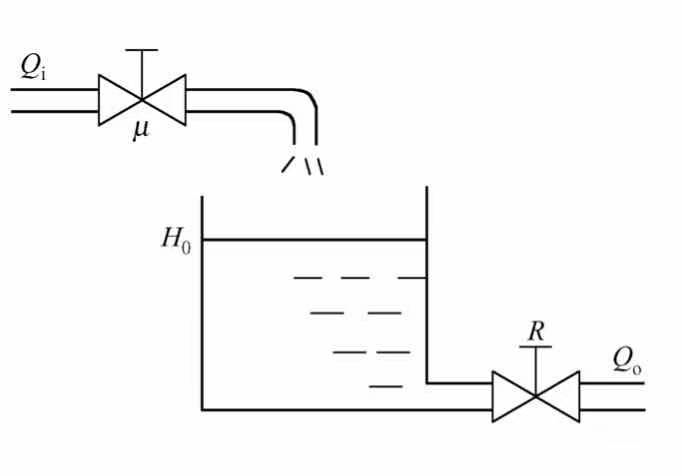

% 定义系统参数
F1 = 28; % 水槽截面积
R1 = 0.071; % 水槽出口管道阻力系数
Ku = 3.33; % 水泵增益

% 定义时间常数和传递系数
T1 = F1*R1;
K = Ku*R2;

% 定义传递函数
s = tf('s');
G = K/(T1*s^1 + 1)

G =
 
    0.1898
  -----------
  1.988 s + 1
 
Continuous-time transfer function.



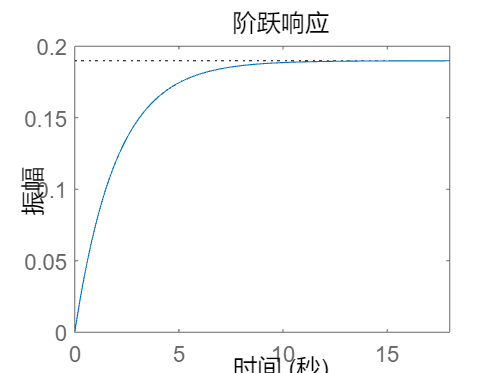


% 绘制系统阶跃响应曲线
step(G);

2.2 双容水槽的建立

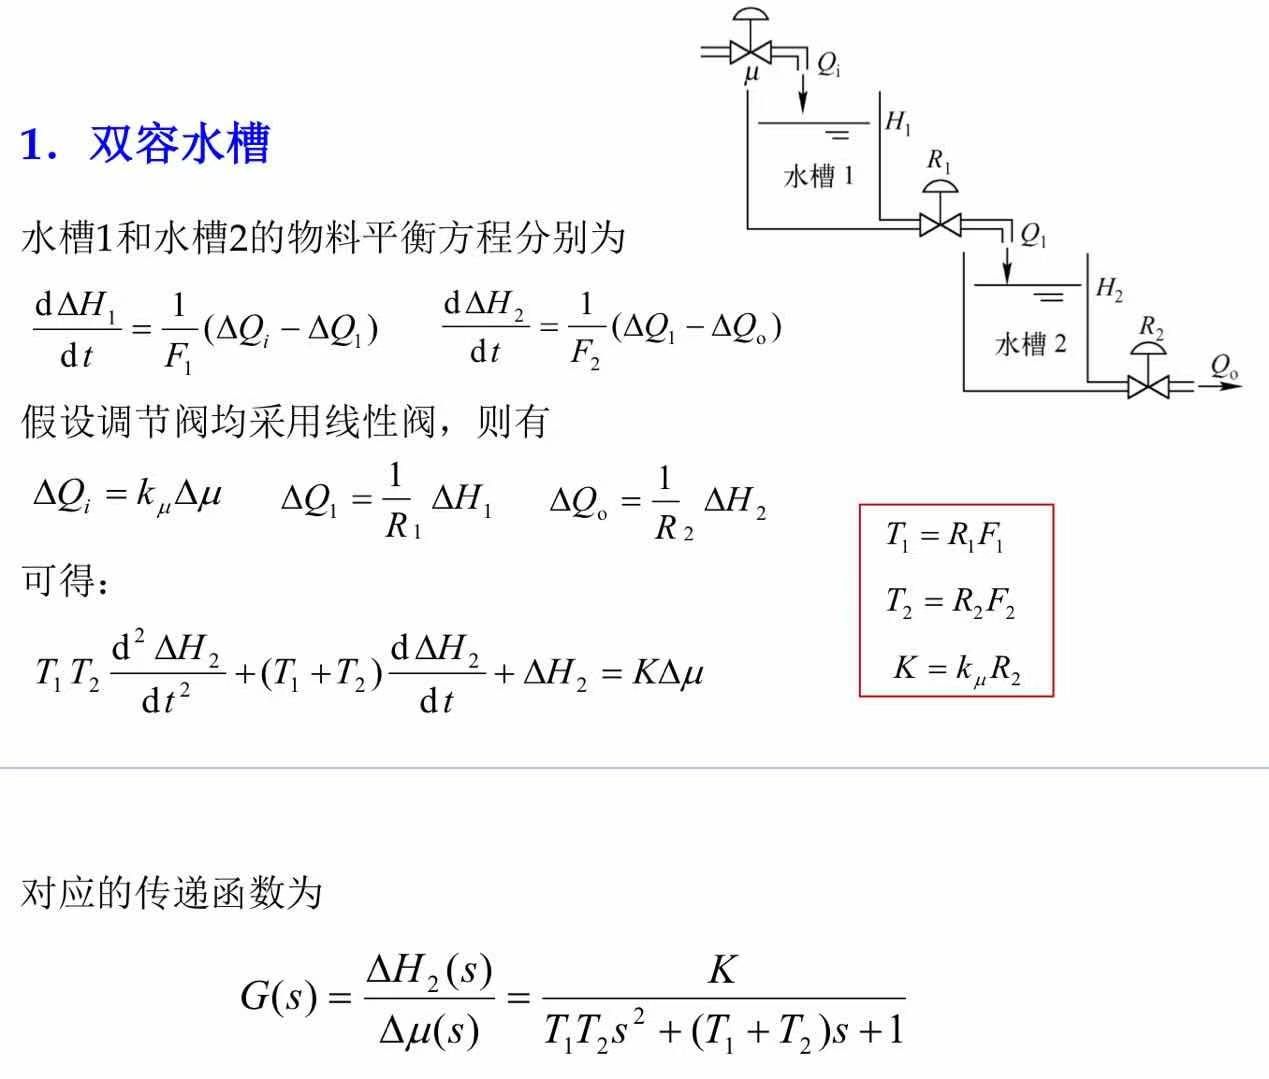

% 定义系统参数
F1 = 28; % 第一个水槽截面积
F2 = 32; % 第二个水槽截面积
R1 = 0.071; % 第一个水槽出口管道阻力系数
R2 = 0.057; % 第二个水槽出口管道阻力系数
Ku = 3.33; % 水泵增益

% 定义时间常数和传递系数
T1 = F1*R1;
T2 = F2*R2;
K = Ku*R2;

% 定义传递函数
s = tf('s');
G = K/(T1*T2*s^2 + (T1+T2)*s^1 + 1)

G =
 
          0.1898
  -----------------------
  3.626 s^2 + 3.812 s + 1
 
Continuous-time transfer function.



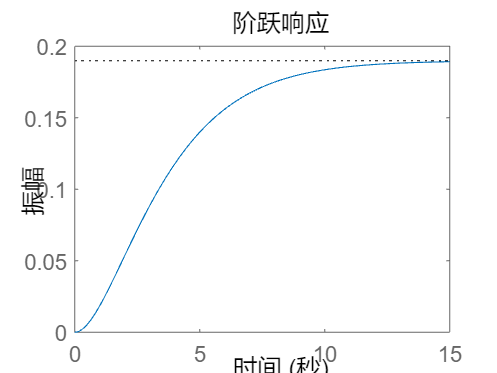


% 绘制系统阶跃响应曲线
step(G);


%考虑延时环节
tao = -2;
G1 = (K*exp(tao*s))/(T1*T2*s^2 + (T1+T2)*s^1 + 1)

G1 =
 
                      0.1898
  exp(-2*s) * -----------------------
              3.626 s^2 + 3.812 s + 1
 
Continuous-time transfer function.



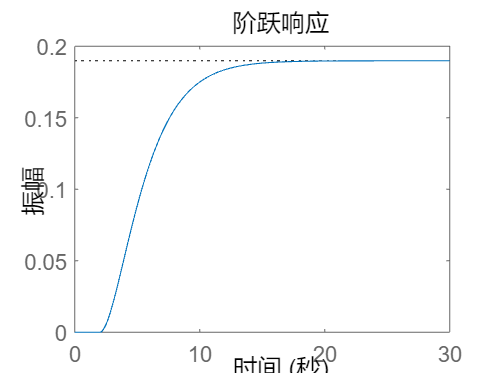

step(G1);


%simulink
% out = sim('part2_1.slx',100);
% out.plot
